filenameVRS = "C:\Users\silva.LSMEDIT\Documents\sciebo\ProjektSeminar\dataset\subject1\stage1\imgV2.mat";
load(filenameVRS);

filenameCRS = "C:\Users\silva.LSMEDIT\Documents\sciebo\ProjektSeminar\dataset\subject1\stage1\imgB2.mat";
load(filenameCRS);

perfCm = buildcmap('yrk');
barCm = buildcmap('bwr');

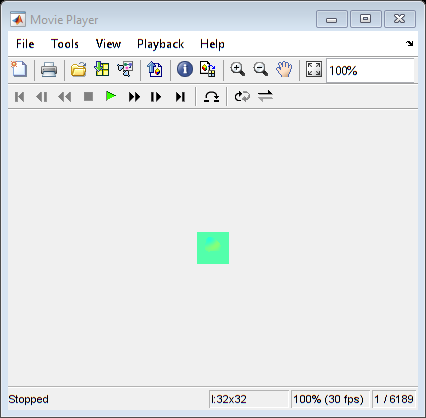

% Organize the data into "snapshots": spatial is rows, time is columns
heartPix = [7,15];
lungPix = [14,22];

% VRS
stdMap = std(imgV2,[],3);
imgV2Filt = imgV2 .* repmat(stdMap > max(stdMap(:)) * 0.5, 1, 1, size(imgV2, 3));
flatV = reshape(imgV2Filt(:,:,1000:end),32*32,[]);

playVideo(imgV2Filt);

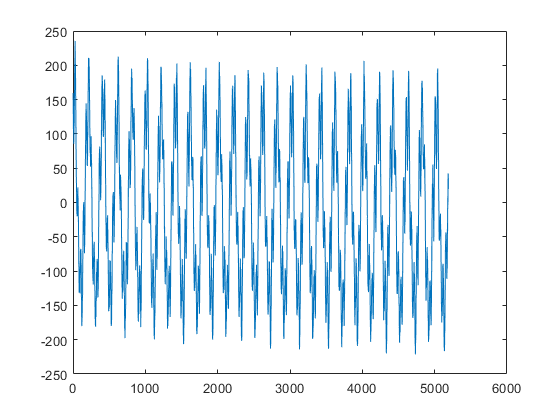


figure; plot(squeeze(imgV2(heartPix(1),heartPix(2),1000:end)));

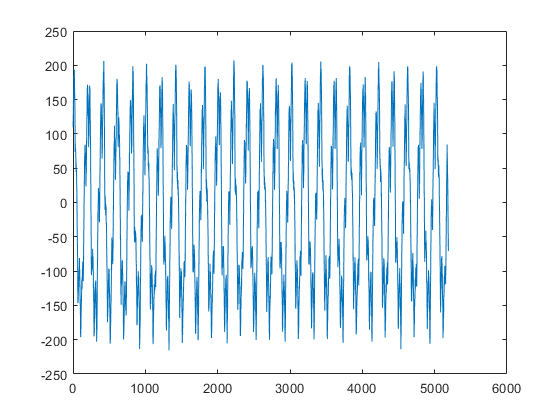

figure; plot(squeeze(imgV2(lungPix(1),lungPix(2),1000:end)));

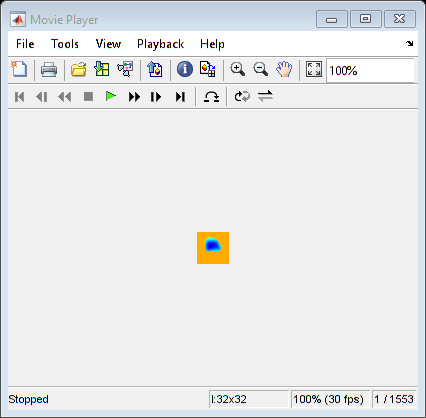

% CRS - ground truth
imgB2Filt = imgB2 .* repmat(stdMap > max(stdMap(:)) * 0.5, 1, 1, size(imgB2, 3));
flatC = reshape(imgB2Filt(:,:,250:end),32*32,[]);

playVideo(imgB2Filt);

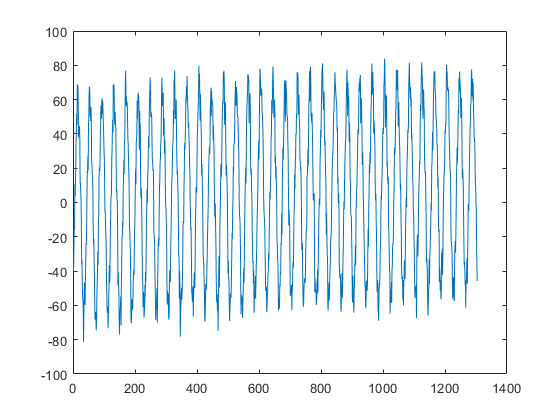


figure; plot(squeeze(imgB2(heartPix(1),heartPix(2),250:end)));

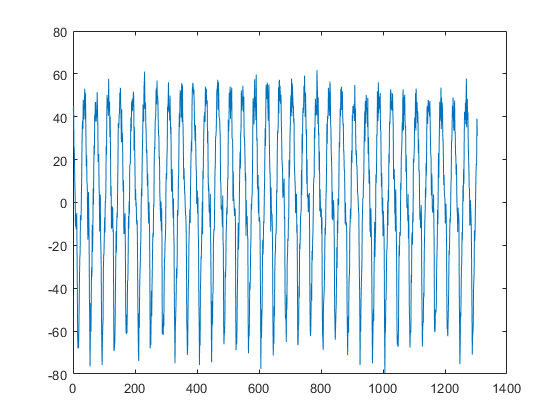

figure; plot(squeeze(imgB2(lungPix(1),lungPix(2),250:end)));

% Initialize DMD class and properties
dmd = DMD();
rank = 20;
fs = 50;

nLevels = 4;
freqLims = [1,10];
damLims = [0.9, 1];
magLims = [0, 1];

dataWindow = 200;
predWindow = 5; % minimize

start = 1;
finish = start + dataWindow; 
sigLen = size(flatV,2);
perfSig = [];
realTime = [];
while finish < sigLen
    X = flatV(:,start:finish);
    Y = flatV(:,start + 1:finish + 1);
    
    tSize = size(X, 2);
    
    tic
    [lambda, omega, Phi, b] = mrFit(dmd,  X, Y, fs, nLevels, tSize);

    [norms, mags, freqs] = interpModes(dmd, lambda, Phi, b);
    [~, ~, ~, lambda, omega, Phi, b] = boxSelection(dmd, norms, mags, freqs, ...
                                                    lambda, omega, Phi, b, ....
                                                    magLims, damLims, freqLims);
    execTime = toc;
    
    if execTime < 1/fs * predWindow
        realTime = [realTime,1];
    else
        realTime = [realTime,0];
    end
    
    tSize = tSize + predWindow;
    [~, Xtotal] = reconData(dmd, lambda, omega, Phi, b, tSize, fs, 'disc');
    perfSig = [perfSig,real(Xtotal)];
    
    start = start + tSize;
    finish = start + dataWindow;
end

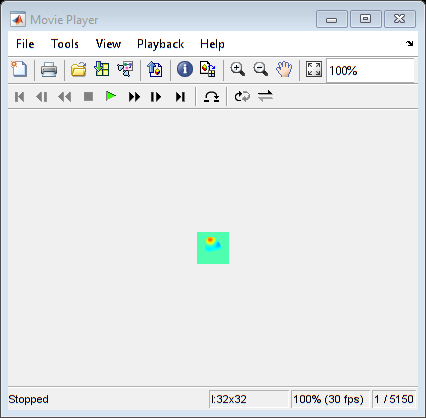

perfImg = real(reshape(perfSig,32,32,[]));
playVideo(perfImg);

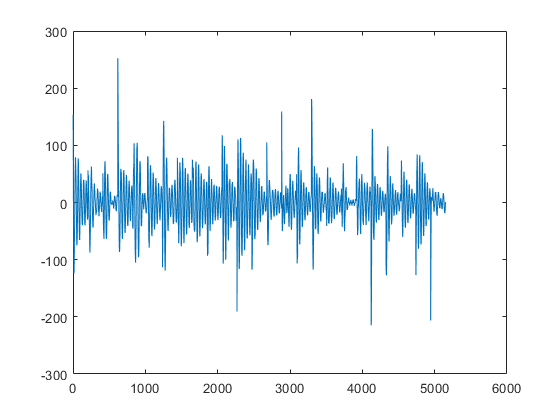

figure; plot(squeeze(perfImg(heartPix(1),heartPix(2),:)));

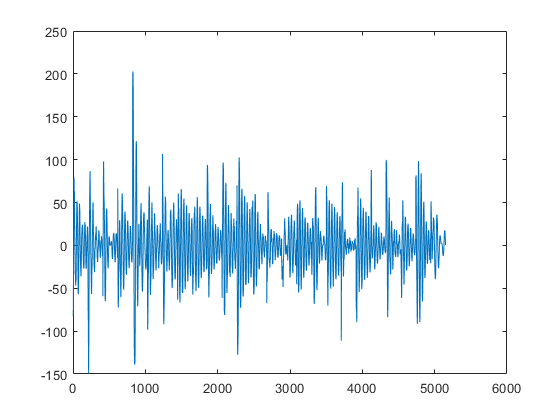

figure; plot(squeeze(perfImg(lungPix(1),lungPix(2),:)));